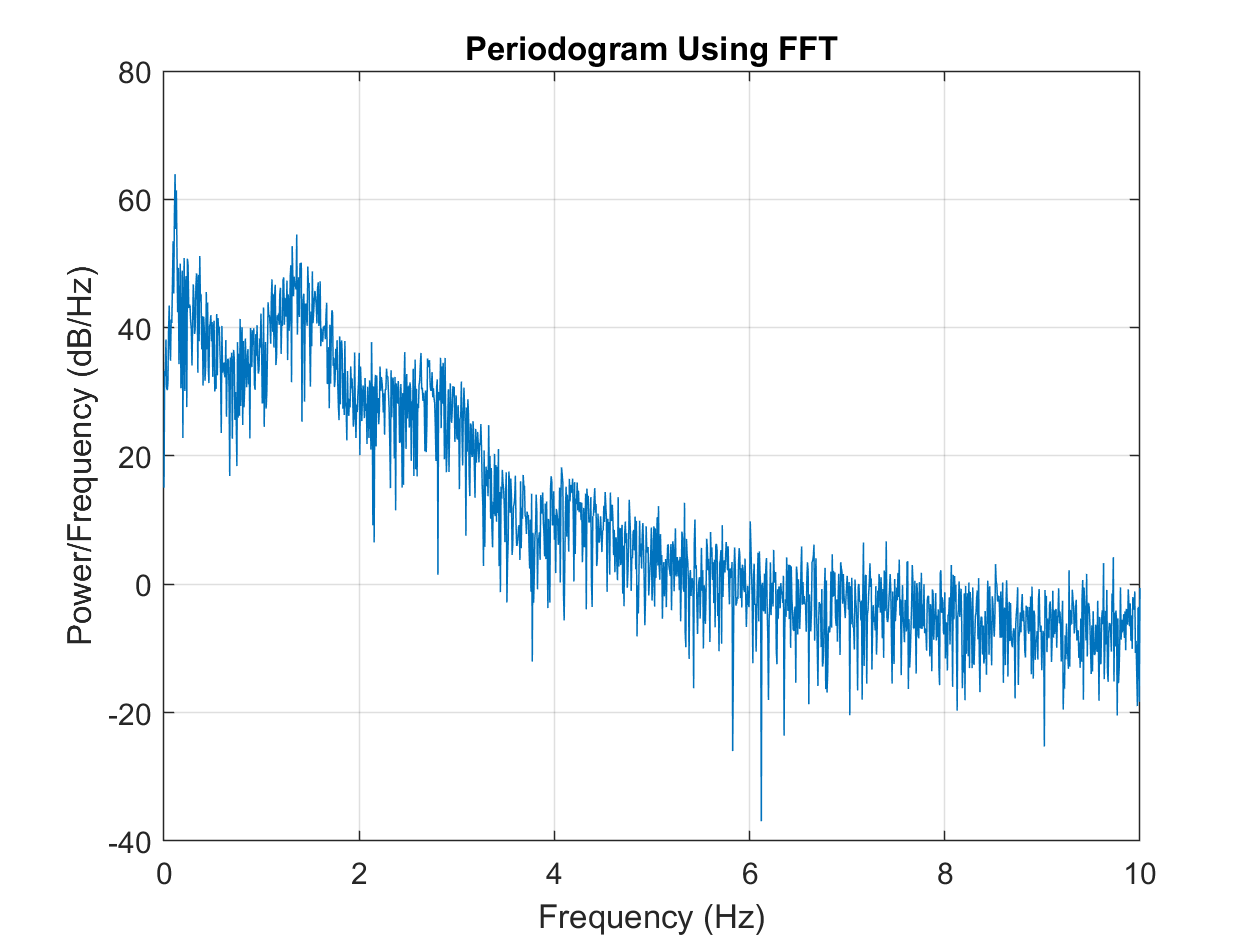

Fs=20;
N = length(Signal2);
xdft = fft(Signal2);
xdft = xdft(1:N/2+1);
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/length(Signal2):Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')